# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 30, 2020

- Location: Locomotion Laboratory

- Subject: XD

- Quarq calibration factor: 336

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 20.4

- Humidity (%): 50.0

- Pressure (mmHg): 632           

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 16;
code = {'xd'};
sex = {'m'};
age = 36;
mass = 150; %lb
h = 1.82; %m

T = table(number,code,sex,age,mass,h)

## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.06; 0.1; 0.14; 0.18];
listHang = listPerc * mass

### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

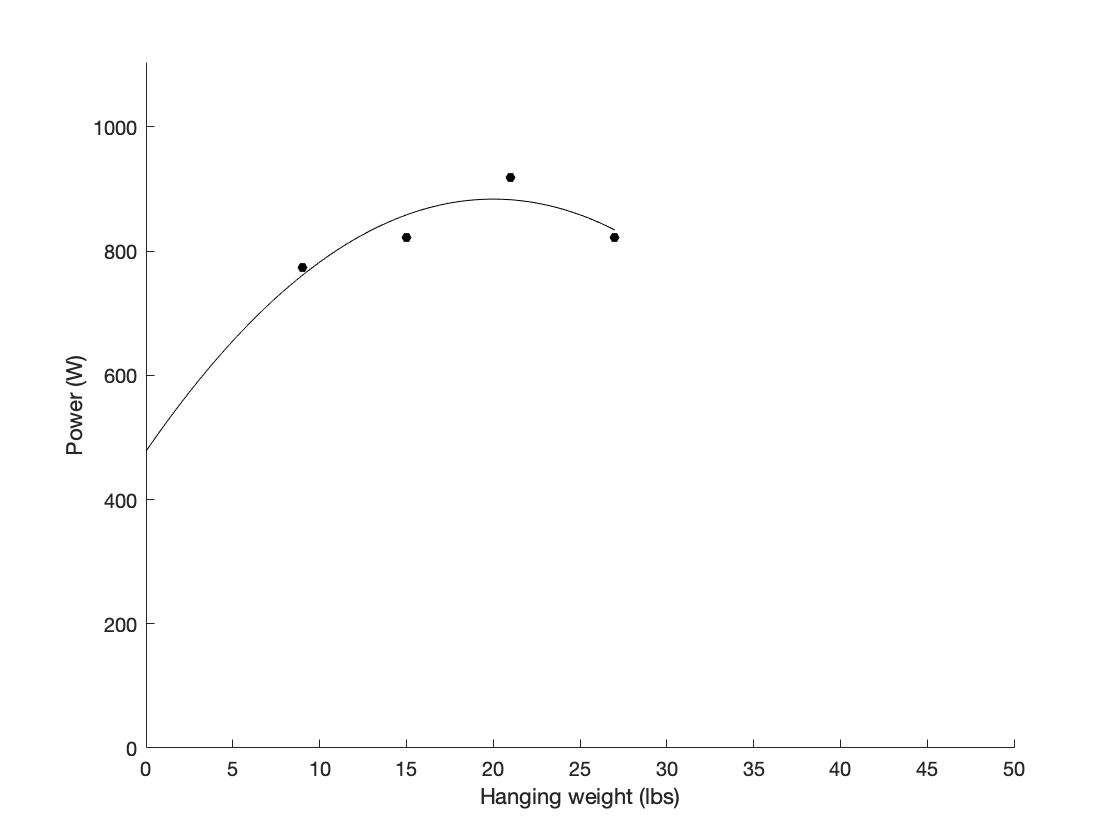

x = [9; 15; 21; 27]; % hanging weight
x_ = [144; 130; 92; 75]; % cadence
y = [773; 822; 919; 822]; % power output

% fit curve: power vs hang
%[c, ~, ~] = fit(x,y,'poly3','Lower',[-Inf -Inf -Inf 0],'Upper',[Inf Inf Inf 0]);
[c, ~, ~] = fit(x,y,'poly2');

new_x = 0:max(x)/(max(x)*2):max(x);
%new_y = c.p1*new_x.^3 + c.p2*new_x.^2 + c.p3*new_x + c.p4;
new_y = c.p1*new_x.^2 + c.p2*new_x + c.p3;

% plot curve: power vs hang
scatter(x,y,25,'k','filled');
hold on
plot(new_x,new_y,'k-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 883.70 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 20.00 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      1     2     3


randperm(3)

ans =      3     2     1


randperm(3)

ans =      2     3     1


### Experimental results

Record results to array then convert to table.

data = [
    16, 1, 1, 20, 918, 100;
    16, 2, 1, 20, 851, 97;
    16, 3, 1, 20, 901, 102;
    16, 3, 2, 20, 910, 103;
    16, 2, 2, 20, 890, 99;
    16, 1, 2, 20, 918, 101;
    16, 2, 3, 20, 910, 101;
    16, 3, 3, 20, 955, 100;
    16, 1, 3, 20, 894, 99;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

      16           1          1           20           918       100  
      16           2          1           20           851        97  
      16           3          1           20           901       102  
      16           3          2           20           910       103  
      16           2          2           20           890        99  
      16           1          2           20           918       101  
      16           2          3           20           910       101  
      16           3          3           20           955       100  
      16           1          3           20           894        99  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3              910            100   
        2            3           883.67             99   
        3            3              922         101.67   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          13.856             1   
        2            3          30.006             2   
        3            3          28.931        1.5275   


## Lean angle analysis

subName = code{:};

Loop through conditions and trials

n = 0;
leanCell = cell(1,9);
for iC = 1:3
    for iT = 1:3
        trialName = ['0',num2str(iC),'0',num2str(iT)];   
        n = n+1;

Load Garmin and IMU data files into tables

        try
            filePath = '/Users/rosswilkinson/Google Drive/projects/rock-no-rock/data/';
            fileName = [subName '_' trialName '_power'];
            tP = readtable([filePath fileName]);
            
            filePath = '/Users/rosswilkinson/Google Drive/projects/rock-no-rock/data/';
            fileName = [subName '_' trialName '_crank'];
            tC = readtable([filePath fileName]);
            
            filePath = '/Users/rosswilkinson/Google Drive/projects/rock-no-rock/data/';
            fileName = [subName '_' trialName '_frame'];
            tF = readtable([filePath fileName]);      
        catch
            warning('Missing required file. Assigning NaN to lean angle.')
            k = T_.condition == iC & T_.trial == iT;
            T_.lean(k) = NaN;
            continue
        end
        
        try
            [leanAngle, leanRange, leanArray, tP_, tF_, tC_] = calculateLeanAngle(tP,tF,tC);
            leanCell{n} = leanArray;
        catch
            warning('Sync error. Assigning NaN to lean angle.')
            k = T_.condition == iC & T_.trial == iT;
            T_.lean(k) = NaN;
            continue
        end

Store peak lean angle in subject data table

        k = T_.condition == iC & T_.trial == iT;
        T_.lean(k) = leanAngle;

Plot power, frame angle, and crank accel.

        figure('Name',trialName)
        subplot(321)
        plot(tP_.secs,tP_.watts)
        subplot(323)
        plot(tC_.timestamp,tC_.accel_x_m_s2_)
        subplot(325)
        plot(tF_.timestamp,tF_.accel_y_m_s2_)

Plot acc, vel, and dis

        subplot(322)
        plot(tF_.thetaAcc)
        subplot(324)
        plot(tF_.thetaVel)
        subplot(326)
        plot(tF_.thetaPos)

Plot lean angle during each crank cycle

        figure("Name",[trialName '_lean'])
        plot(leanArray)
    end
end

Calculate mean and SD range of lean angle for experimental trials.

varfun(@(x) mean(x,'omitnan'),T_,'InputVariables',{'lean'}, ...
    'GroupingVariables',{'condition'})
varfun(@(x) std(x, 'omitnan'),T_,'InputVariables',{'lean'}, ...
    'GroupingVariables',{'condition'})